Esercizio 1: blue white red

- Definisco la colormap

n = 100;
r = [ones(n/2,1);linspace(1,0,n/2)'];
g = [linspace(0,1,n/2)';linspace(1,0,n/2)'];
b = [linspace(0,1,n/2)';ones(n/2,1)];

bwr = [r, g, b];

- Definisco la funzione

M = load_off('../../05_viz/code/tr_reg_000.off');

f = zeros(M.n,1);
for i=1:M.n
    f(i) = sum(pdist2(M.VERT(i,:),M.VERT));
end

- Plotto f usando la colormap bwr

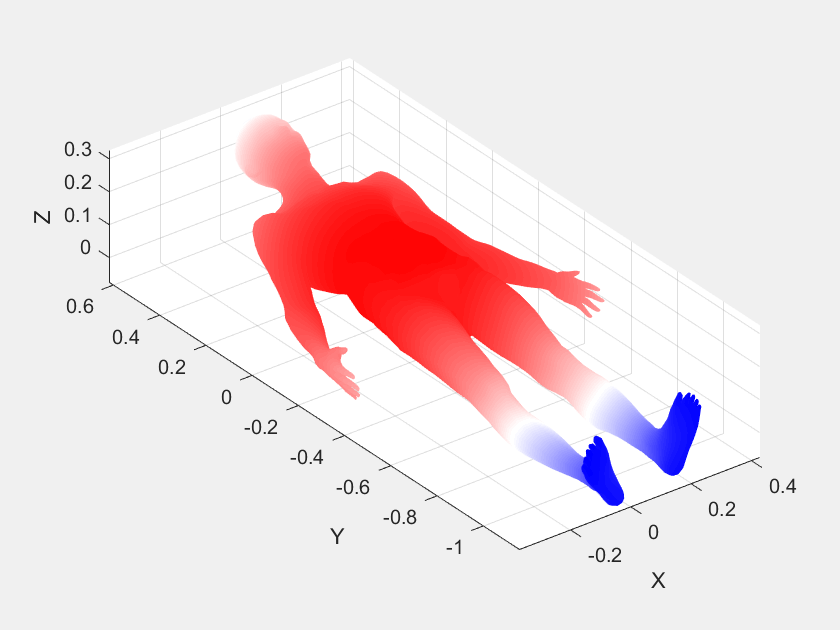

ans =   Patch with properties:

    FaceColor: 'interp'
    FaceAlpha: 1
    EdgeColor: 'none'
    LineStyle: '-'
        Faces: [13776×3 double]
     Vertices: [6890×3 double]

  Show all properties


figure, colormap(bwr)
plot_scalar_map(M,f)